# Import Relevant Files & Extract Variables

% Get file paths
burnsideRadianceDir2024 = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Burnside/Summer 2024/Burnside Radiances 2024.csv'];
gaultRadianceDir2024 = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Gault/Summer 2024/Gault Radiances 2024.csv'];
burnsideRadianceDir2025 = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Burnside/Summer 2025/Burnside Radiances 2025.csv'];


% Create timetables from files
burnsideRadianceUntitled2024 = readtimetable(burnsideRadianceDir2024);
% Read the Burnside radiance data for 2025
burnsideRadianceUntitled2025 = readtimetable(burnsideRadianceDir2025);
gaultRadianceUntitled2024 = readtimetable(gaultRadianceDir2024);

allVariables = 1:width(burnsideRadianceUntitled2024);

% Fix the column titles & extract wavenumber
wavenumbers = table2array(burnsideRadianceUntitled2024(1, :));
newTitle = string(wavenumbers);
burnsideRadianceUntitled2024(1, :) = [];
gaultRadianceUntitled2024(1, :) = [];

% Annoying that I have to do this, but whatever
burnsideRadiance2024 = renamevars(burnsideRadianceUntitled2024, allVariables, newTitle);
burnsideRadiance2025 = renamevars(burnsideRadianceUntitled2025, allVariables, newTitle);
gaultRadiance2024 = renamevars(gaultRadianceUntitled2024, allVariables, newTitle);

# Create Timetable(s) for Relevant Wavenumber(s)

cloudEmissionBandsMin = 985;
cloudEmissionBandsMax = 998;

% Get the index
cloudIndices = find(cloudEmissionBandsMin <= wavenumbers & wavenumbers <= cloudEmissionBandsMax);

% Create timetable(s)
cloudTimeTableBurnside2024 = burnsideRadiance2024(:, cloudIndices);
meanCloudTimeTableBurnside2024 = mean(cloudTimeTableBurnside2024, 2);
cloudTimeTableBurnside2025 = burnsideRadiance2024(:, cloudIndices);
meanCloudTimeTableBurnside2025 = mean(cloudTimeTableBurnside2025, 2);
cloudTimeTableBurnside = [meanCloudTimeTableBurnside2024; meanCloudTimeTableBurnside2025];
cloudTimeTableGault = gaultRadiance2024(:, cloudIndices);
cloudTimeTableGault2024 = mean(cloudTimeTableGault, 2);

# Use NOAA Conversion

% Create brightness Time Tables
brightnessTableBurnside = zeros(size(cloudTimeTableBurnside));
brightnessTableGault = zeros(size(cloudTimeTableGault2024));

% Define constants based on NOAA numbers
a = 1.191042 * 10^(-8);
b = 1.4387752;
v = 991.5;

% Convert Burnside Radiances to brightness temperatures
    
for j = 1:height(cloudTimeTableBurnside)
    B = cloudTimeTableBurnside.mean(j);
    t = b*v/(log((a*v^3)/(B/1000) + 1));
    brightnessTableBurnside(j) = t;

end


% Convert Gault radiances to brightness temperatures
    
for j = 1:height(cloudTimeTableGault2024)
    B = cloudTimeTableGault2024.mean(j);
    t = b*v/(log((a*v^3)/(B/1000) + 1));
    brightnessTableGault(j) = t;
end


# Find Probabiliy Sky Will Be a Certain Temperature  

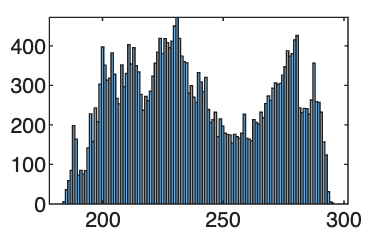

% Use all available values
fullTable = [brightnessTableBurnside; brightnessTableGault];

selectedTable = round((fullTable));
selectedTable(isnan(selectedTable)) = [];
selectedTable = nonzeros(selectedTable);

% selectedTable = selectedTable + 40;

uniqueTemperatures = unique(selectedTable);

% Count the number of observations for each value
observationCounts = (histcounts(selectedTable, 'BinMethod', 'integers'))';

histogram(selectedTable, length(uniqueTemperatures))



% for i = 1:width(brightnessTableGault)
%     % Clean table
%     selectedTable = round(brightnessTableGault(:, 2));
%     selectedTable(isnan(selectedTable)) = [];
%     selectedTable = (nonzeros(selectedTable));
% 
% 
%     % Find the unique values of temperature in this data
%     uniqueTemperatures = unique(selectedTable);
% 
%     % Count the number of observations for each value
%     observationCounts = histcounts(selectedTable, 'BinMethod', 'integers');
% 
%     histogram(selectedTable, 40)
% end

# Export the Cloud Brightness Table Data to R

baseDirSave = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Cloud Classified Data/'];

% brightnessDistributionBurnside = table(uniqueTemperatures, observationCounts, 'VariableNames', {'Temperatures' 'Count'})

writetable(table(selectedTable, 'VariableNames', {'Temperatures'}), fullfile(baseDirSave, "Burnside Brightness.csv"))
writematrix(brightnessTableGault, fullfile(baseDirSave, "Gault Brightness.csv"))